# Discrete-time models- Lab 5

Zhu Chenhao

22320630

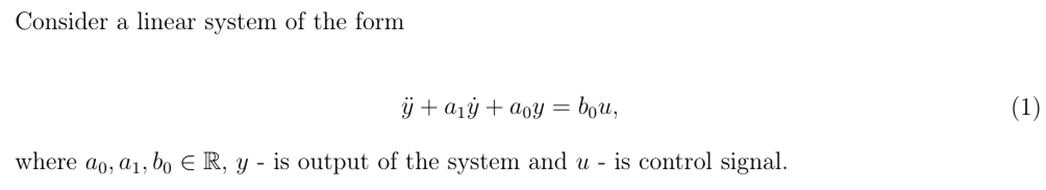

hwc = hwc_connect('https://dss2025.hdu.vedyakov.com');

Connection established


task = hwc.get_task(5);

## 0. Initial Data

task.parameters

ans = 包含以下字段的 struct :
     T: 2.3000
    a0: 10
    a1: 20
    b0: 1


T = 2.3000;
a0 = 10;
a1 = 20;
b0 = 1;

##  1. State space model

A = [0 1;-a0 -a1];
B = [0; b0];
C = [1 0];
D = 0;

## 2. Eigenvalues

eig_value = eig(A)

eig_value =    -0.5132
  -19.4868


eig_value_continuous_1 = eig_value(2,1);
eig_value_continuous_2 = eig_value(1,1);

## 3. Discrete system

sys = ss(A, B, C, D);
Ad =  expm(A*T);
Bd = A \ (Ad - eye(size(A)))*B;

## 4. Eigenvalues of a discrete system

sysd = ss(Ad, Bd, C, D, T);
eig_value_d = eig(Ad);
eig_value_discrete_1 = eig_value_d(2,1);
eig_value_discrete_2 = eig_value_d(1,1);

## 5. Stepinfo to find the number of steps

step_info = stepinfo(sysd);
disp(step_info);

         RiseTime: 2.3000
    TransientTime: 9.2000
     SettlingTime: 9.2000
      SettlingMin: 0.0903
      SettlingMax: 0.1000
        Overshoot: 2.2204e-14
       Undershoot: 0
             Peak: 0.1000
         PeakTime: 75.9000



transient_time = step_info.TransientTime; 
num_steps_until_end_of_transient = transient_time / T

num_steps_until_end_of_transient = 4

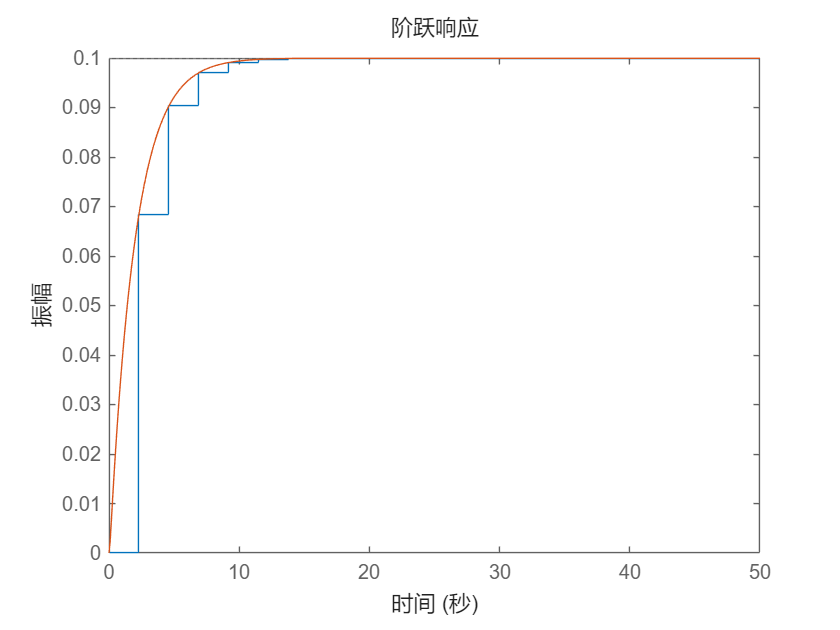

step(sysd, sys)

## 6. Using ode45 and input signal u(t) = 1

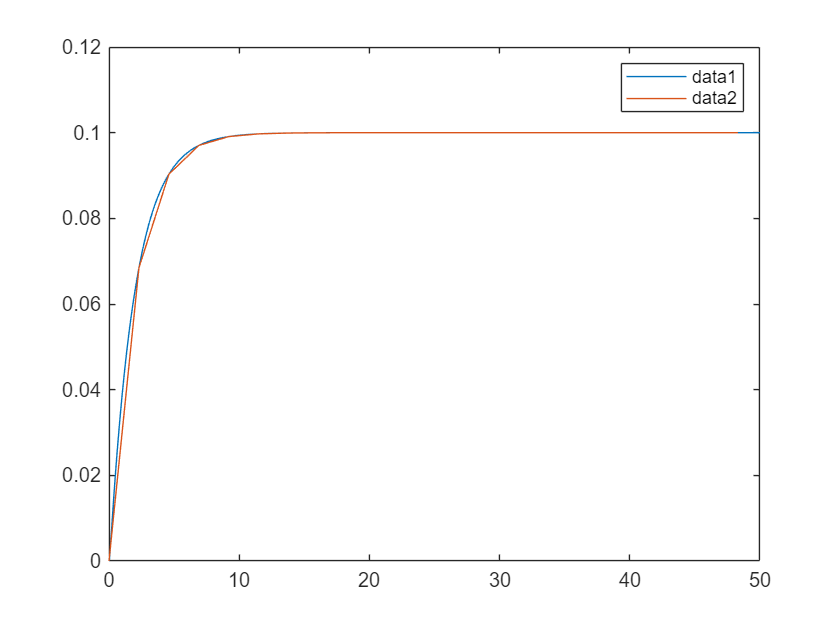

u = 1;
tspan = [0 50];
x0 = [0; 0];
sol = ode45(@(t,x) odefun(t,x,u,a0,a1,b0),tspan,x0);
plot(sol.x,sol.y(1,:))
hold on;
t_d = 0:T:50;
n = length(t_d);
x_d = zeros(2,n);
x_d(:, 1) = x0;
for k = 1:n-1
    x_d(:, k+1) = Ad*x_d(:, k)+Bd*u;
end
plot(t_d, x_d(1, :))
legend show;
hold off;

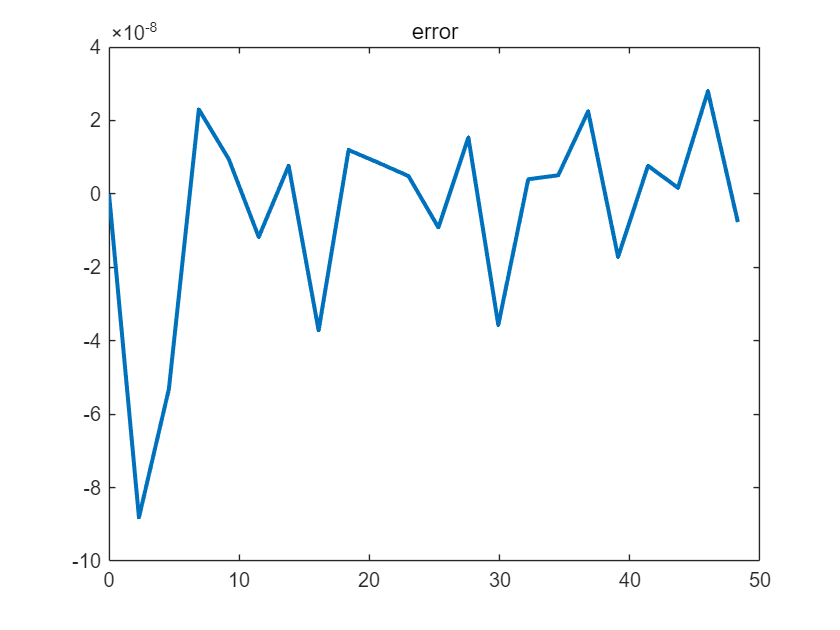

y_kt = x_d(1, :);
for k = 1:n
    y_t(:,k) = deval(sol, t_d(k));
end
plot(t_d, y_t(1, :) - y_kt, 'LineWidth', 2);
title("error")

## 7. Input signal u(t) = 2*sin(4*t)

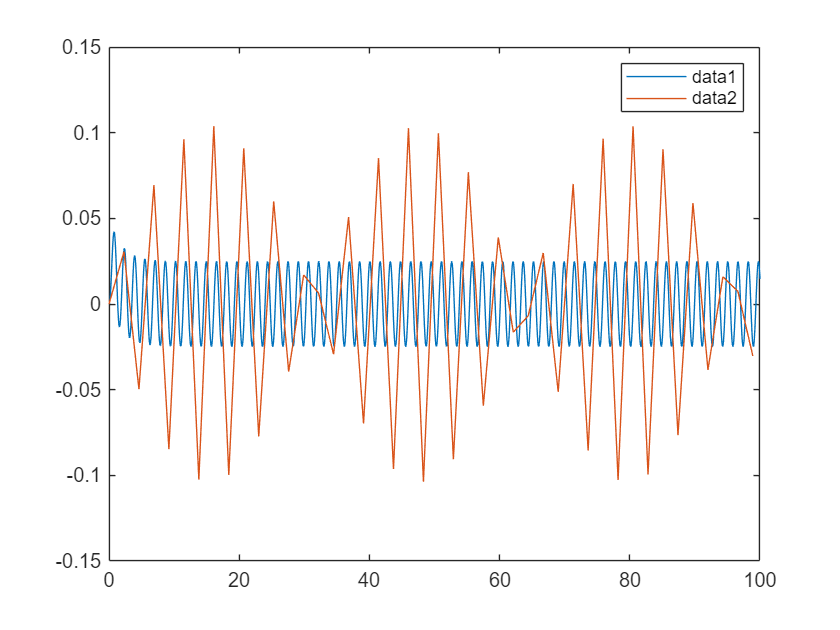

tspan = [0 100];
x0 = [0; 0];
sol = ode45(@(t,x) odefun2(t,x,a0,a1,b0), tspan, x0);
plot(sol.x, sol.y(1,:))
hold on;
t_d2 = 0:T:100;
n = length(t_d2);
x_d = zeros(2, n);
x_d(:, 1) = x0;
u_d = zeros(1,n);
for k = 1:n-1
    u_d(1, k) = 2*sin(4*k*T);
    x_d(:, k+1) = Ad*x_d(:, k) + Bd * u_d(1, k);
end
plot(t_d2, x_d(1,:))
legend show;
hold off;

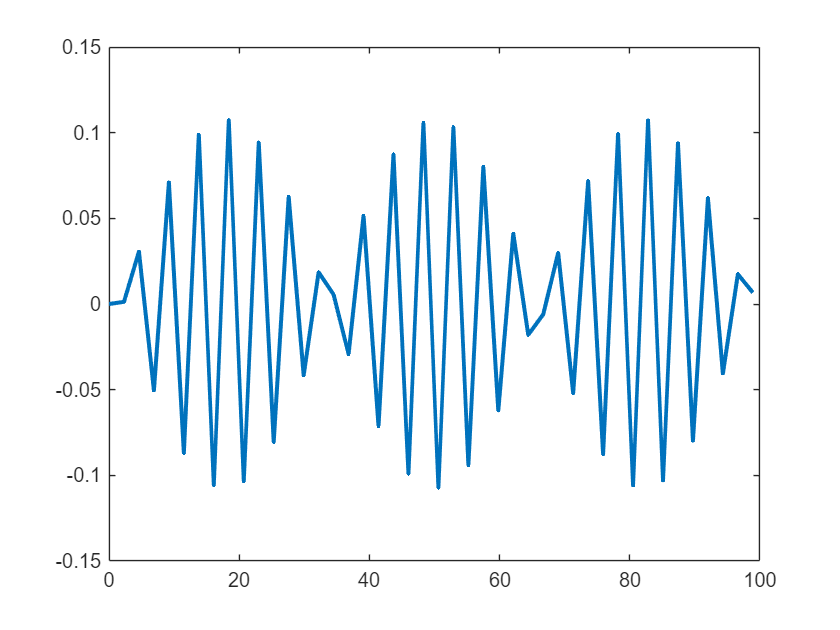


y2_kt = x_d(1, :);
for k = 1:n
    y2_t(:, k) = deval(sol, t_d2(k));
end
plot(t_d2, y2_t(1, :) - y2_kt, 'LineWidth', 2);

## 8. Plot the graphs

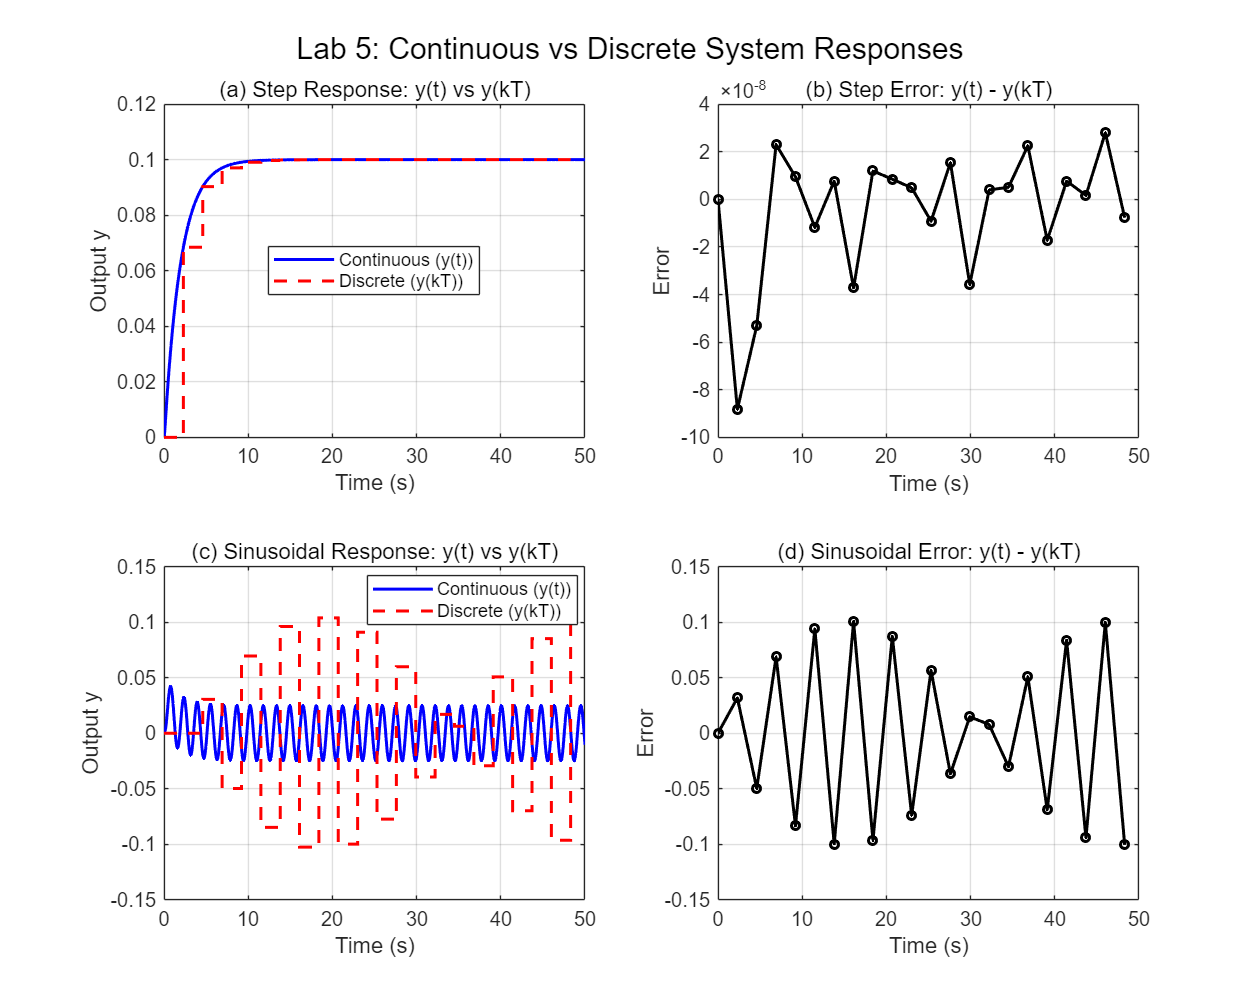

%% Task 8: Plot the graphs
figure;

% --- (a) Plot y(t) and y(kT) for u(t) = 1 ---
subplot(2, 2, 1);
tspan = [0 50];
sol = ode45(@(t,x) odefun(t,x,u,a0,a1,b0), tspan, x0);
plot(sol.x, sol.y(1, :), 'b', 'LineWidth', 1.5); % Continuous solution
hold on;

% 离散系统响应
t_d = 0:T:50; % 时间向量
n = length(t_d);
x_d = zeros(2, n);
x_d(:, 1) = x0;
for k = 1:n-1
    x_d(:, k+1) = Ad * x_d(:, k) + Bd * u;
end
stairs(t_d, x_d(1, :), 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Output y');
title('(a) Step Response: y(t) vs y(kT)');
legend('Continuous (y(t))', 'Discrete (y(kT))', 'Location', 'best');
grid on;
hold off;

% --- (b) Plot y(t) - y(kT) for u(t) = 1 ---
subplot(2, 2, 2);
y_t = deval(sol, t_d); % 现在 t_d 在 sol.x 范围内
plot(t_d, y_t(1, :) - x_d(1, :), 'ko-', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Time (s)');
ylabel('Error');
title('(b) Step Error: y(t) - y(kT)');
grid on;

% --- (c) Plot y(t) and y(kT) for u(t) = 2*sin(4t) ---
subplot(2, 2, 3);
% 重新求解 ode45，时间范围与 t_d2 一致
tspan = [0 50];
sol_sin = ode45(@(t,x) odefun2(t,x,a0,a1,b0), tspan, x0);
plot(sol_sin.x, sol_sin.y(1, :), 'b', 'LineWidth', 1.5);
hold on;

% 离散系统响应
t_d2 = 0:T:50;
n2 = length(t_d2);
x_d2 = zeros(2, n2);
x_d2(:, 1) = x0;
for k = 1:n2-1
    u_k = 2 * sin(4 * t_d2(k));
    x_d2(:, k+1) = Ad * x_d2(:, k) + Bd * u_k;
end
stairs(t_d2, x_d2(1, :), 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Output y');
title('(c) Sinusoidal Response: y(t) vs y(kT)');
legend('Continuous (y(t))', 'Discrete (y(kT))', 'Location', 'best');
grid on;
hold off;

% --- (d) Plot y(t) - y(kT) for u(t) = 2*sin(4t) ---
subplot(2, 2, 4);
y2_t = deval(sol_sin, t_d2);
plot(t_d2, y2_t(1, :) - x_d2(1, :), 'ko-', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Time (s)');
ylabel('Error');
title('(d) Sinusoidal Error: y(t) - y(kT)');
grid on;

% 调整图形布局
sgtitle('Lab 5: Continuous vs Discrete System Responses');
set(gcf, 'Position', [100, 100, 1000, 800]);

**Because my sampling time TsTs� is relatively large, the discrete data does not fit well.**

## Answers

task.answers.eig_value_continuous_1 = eig_value_continuous_1;
task.answers.eig_value_continuous_2 = eig_value_continuous_2;
task.answers.eig_value_discrete_1 = eig_value_discrete_1;
task.answers.eig_value_discrete_2 = eig_value_discrete_2;
task.answers.steps_transition_process = num_steps_until_end_of_transient;
task.answers

ans = 包含以下字段的 struct :
      eig_value_continuous_1: -19.4868
      eig_value_continuous_2: -0.5132
        eig_value_discrete_1: 1.7347e-18
        eig_value_discrete_2: 0.3072
    steps_transition_process: 4


hwc.send_task(task)

You have 37 attempts left


ans = 包含以下字段的 struct :
      eig_value_continuous_1: 0.5000
      eig_value_continuous_2: 0.5000
        eig_value_discrete_1: 0.5000
        eig_value_discrete_2: 0.5000
    steps_transition_process: 1
                 total_score: 3


function dx = odefun(t, x, u, a0, a1, b0)
    A = [0 1;-a0 -a1];
    B = [0; b0];
    dx = A*x + B*u;
end

%%
function dx = odefun2(t, x, a0, a1, b0)
    u = 2 * sin(4 * t); 
    A = [0 1;-a0 -a1];
    B = [0; b0];
    dx = A*x + B*u;
end